. 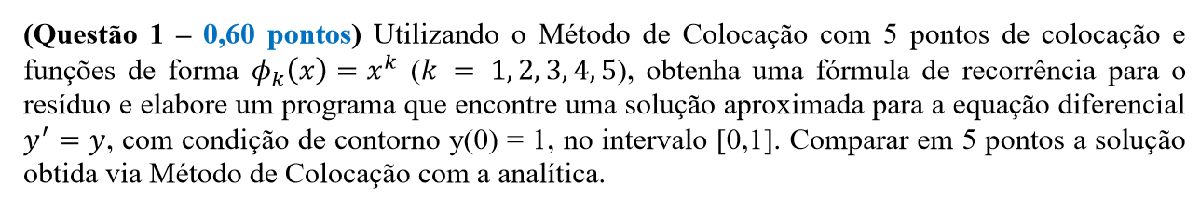

Método de Colocação 

k = 5 , intervalo [0,1], C.C y(0)=1 


$$\begin{array}{l}
\phi_k \left(x\right)=x^k \\
\mathrm{y'}=y\text{  }\to \frac{\mathrm{y'}}{y}=1\text{   }\mathrm{resolvendo}\text{ }a\text{ }\mathrm{EDO}\to \int \frac{\mathrm{y'}}{y}\mathrm{dx}=\int 1\text{ }\mathrm{dx}\to \mathrm{ln}\left(y\right)=x\text{ }+C\to y=e^{x+C} \text{ }\to y=e^x e^C \\
y\left(0\right)=e^0 e^C =1\to e^C =1\text{ }\mathrm{aplicando}\text{ }o\text{ }\mathrm{ln}\text{ }\mathrm{em}\text{ }\mathrm{ambos}\text{ }\mathrm{os}\text{ }\mathrm{lados}\to \mathrm{ln}\left(e^C \right)=\mathrm{ln1}\to C=\mathrm{ln1}\to C=0\\
\mathrm{logo}\text{ }y=e^x \text{ }é\text{ }a\text{ }\mathrm{função}\text{ }\mathrm{analítica}\text{ }
\end{array}$$


Determinar uma função F(x) aproximada a função y(x) através do somatorio da função $\phi_k \left(x\right)$


$$\begin{array}{l}
F\left(x\right)=\sum_{k=0}^{5} A_k x^k \text{ }\to F\left(x\right)=A_0 x^0 +A_1 x^1 +A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \\
F\left(x\right)=A_0 +A_1 x^1 +A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \to F\left(0\right)=1\text{ }\left(\text{sobra}\text{ }\text{apenas}\text{ }o\text{ }\text{termo}\text{ }\text{independente}\right)\to A_0 =1\\
F\left(x\right)=1+A_1 x+A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \text{ }\text{ }\text{ }=1+\sum_{k=1}^{5} A_k x^k \text{    }\|\text{    }\text{ }\text{F'}\left(x\right)=A_1 +{2A}_2 x+{3A}_3 x^2 +{4A}_4 x^3 +{5A}_5 x^4 \text{ }=\sum_{k=1}^{5} A_k kx^{k-1} \text{ }\\
\text{Se}\text{ }\text{y'}=y\text{ }\to \text{y'}-y=0\iff \text{Já}\text{ }\text{para}\text{ }a\text{ }\text{função}\text{ }\text{aproximada}\text{ }\text{F'}=F\to \text{F'}-F=R\left(x\right),\text{onde}\text{ }R\left(x\right)\text{ }é\text{ }o\text{ }\text{residuo}\text{ }\text{gerado}
\end{array}$$


Calculando R(x)


$$\begin{array}{l}
R\left(x\right)=\text{F'}-F\to R\left(x\right)=A_1 +{2A}_2 x+{3A}_3 x^2 +{4A}_4 x^3 +{5A}_5 x^4 -\left\lbrack 1+A_1 x^1 +A_2 x^2 +A_3 x^3 +A_4 x^4 +A_5 x^5 \right\rbrack =\sum_{k=1}^{5} A_k kx^{k-1} -1-\sum_{k=1}^{5} A_k x^k \text{ }\\
\text{igualando}\text{ }R\left(x\right)=0\to \text{  }\text{ }\sum_{k=1}^{5} A_k kx^{k-1} -1-\sum_{k=1}^{5} A_k x^k \text{ }=0\to \sum_{k=1}^{5} A_k kx^{k-1} -\sum_{k=1}^{5} A_k x^k =1\to \sum_{k=1}^{5} A_k \left({kx^{k-1} -x}^k \right)=1
\end{array}$$


Como queremos os coeficientes${\mathrm{Rx}}_k$ de cada $A_k \text{ }\mathrm{com}\text{ }k\text{ }\mathrm{de}\text{ }1\text{ }a\text{ }5\text{ }\mathrm{para}\text{ }\mathrm{cada}\text{ }\mathrm{valor}\text{ }\mathrm{de}\text{ }x$, observando a formula sabemos que cada um pode ser determinado pela seguinte formula:.    ${\mathrm{Rx}}_k =kx^{k-1} -x^k$ 

e o termo independente S =1

Os pontos $x_i \text{ }\mathrm{com}\text{ }i=\text{ }1\text{ }a\text{ }5\text{ }$de interesse x no intervalo [0,1] 

format long
aux=(1-0)/(5+1); %espaçamento
format long
Rx(1:4,1:4)=0;
S(1:4,1)=0;
xi(1:5)=0;
for i=1:5
    xi(i)=i*aux; %vetor que guarda os pontos
    for k = 1:5
       Rx(i,k)=((k*(xi(i))^(k-1))-(xi(i)^k));
    end 
    S(i,1)= 1;
end
    

 Após isso, utilizar o metodo de Eliminação de Gauss para solucionar o sistema e retonar respectivamente os valores de $A_i$ com i variando de 1 para 5

disp (Rx)

   0.833333333333333   0.305555555555556   0.078703703703704   0.017746913580247   0.003729423868313
   0.666666666666667   0.555555555555556   0.296296296296296   0.135802469135802   0.057613168724280
   0.500000000000000   0.750000000000000   0.625000000000000   0.437500000000000   0.281250000000000
   0.333333333333333   0.888888888888889   1.037037037037037   0.987654320987654   0.855967078189300
   0.166666666666667   0.972222222222222   1.504629629629630   1.832561728395061   2.009387860082304



disp (S)

     1
     1
     1
     1
     1



A = metgauss(Rx,S)

A =    1.000213506415868   0.498644234259238   0.171018639110108   0.034588039370581   0.013835215748234


clear aux i  

Logo a função F :


$$F=1+\text{ }1\ldotp 0002x+0\ldotp 4986x^2 +0\ldotp 1710x^3 +0\ldotp 0346x^4 \text{ }+0\ldotp 0138x^5$$


F = @(x)(1+x*A(1)+(x^2)*A(2)+(x^3)*A(3)+(x^4)*A(4)+(x^5)*A(5));
y = @(x)((exp(1))^x);

Comparação dos valores da função exata y com os da função aproximada F

T1=cell(6,3);
T1(1,1)={'Xi'};
T1(1,2)={'Y(Xi)'};
T1(1,3)={'F(Xi)'};
for i=1:5
    T1(i+1,1)={xi(i)};
    T1(i+1,2)={y(xi(i))};
   T1(i+1,3)={F(xi(i))};
end
clear A i y xi F k S Rx
disp(T1)

    'Xi'                   'Y(Xi)'                'F(Xi)'            
    [0.166666666666667]    [1.181360412865646]    [1.181373700279694]
    [0.333333333333333]    [1.395612425086090]    [1.395627388603028]
    [0.500000000000000]    [1.648721270700128]    [1.648739244614301]
    [0.666666666666667]    [1.947734041054676]    [1.947754980037150]
    [0.833333333333333]    [2.300975890892825]    [2.301001345090420]

